disp('1.feladat');

1.feladat


jegy=randi([1 100]);
minosites(jegy);

Jegy
    64

Minősítés:
D




% 2.feladat
disp(' ');

disp('2.feladat');

2.feladat


n=[0.036,0.020,0.015,0.030,0.022];
S=[0.0001,0.0002,0.0012,0.0007,0.0003];
B=[10,8,20,25,15];
H=[2,1,1.5,3,2.6];
disp('n(súrlódási együttható)')

n(súrlódási együttható)


disp(n)

    0.0360    0.0200    0.0150    0.0300    0.0220



disp('S(csatorna meredeksége)')

S(csatorna meredeksége)


disp(S)

    0.0001    0.0002    0.0012    0.0007    0.0003



disp('B(szélesség)')

B(szélesség)


disp(B)

    10     8    20    25    15



disp('H(mélység)')

H(mélység)


disp(H)

    2.0000    1.0000    1.5000    3.0000    2.6000




for i=1:5
U=(sqrt(S(i))/n(i))*((B(i)*H(i))/(B(i)+2*H(i)))^2/3;
fprintf('%i.sebesség(U)=%f\n',i,U)
end

1.sebesség(U)=0.188964
2.sebesség(U)=0.150849
3.sebesség(U)=1.309679
4.sebesség(U)=1.720702
5.sebesség(U)=0.978235



% 3. feladat
disp(' ');

disp('3.feladat');

3.feladat


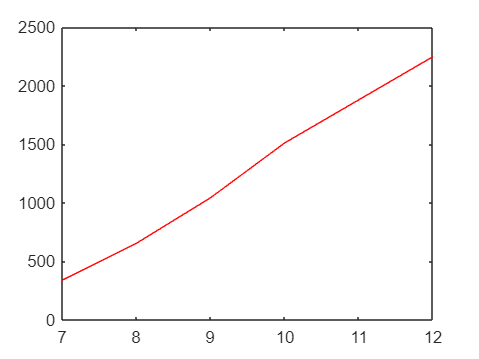

h=[7,8,9,10,12];
r=[3,4,5,6,7];
L=[12,13,14,15,16];
cylinder(r,L,h)

%4.feladat
% tstart = 0;%kezdopont
% tend = 20;%vegsopont
% ni = 8;
% t (1) = tstart ;%az első elemnek a t tömbből adunk értéket, ebben az esetben nullát
% y (1) = 12 + 6* cos (2* pi*t (1)/( tend - tstart ));%az y tömb első elemének adunk értéket egy függvény formájában, felhasználva a t tömb első elemét
% %szükséges értéket adni ennek a két elemnek, mivel fel kell használni a for
% %ciklus elején
% for i = 2: ni +1%a for ciklus 2-től indul mivel nem müködne az első elemre a 0-ik elem hiánya miatt
% t ( i ) = t (i -1)+( tend - tstart )/ ni ;
% y ( i ) = 12 + 6* cos (2* pi*t ( i )/ (tend - tstart ));
% end

%vektorizalas
disp(' ');

disp('4.feladat');

4.feladat




t=20/8:20/8:9*20/8;
y=12+6*cos(2*pi*t)/20;
disp('t');

t


disp(t);

    2.5000    5.0000    7.5000   10.0000   12.5000   15.0000   17.5000   20.0000   22.5000



disp('y');

y


disp(y);

   11.7000   12.3000   11.7000   12.3000   11.7000   12.3000   11.7000   12.3000   11.7000




%5.feladat
disp(' ');

disp('5.feladat');

5.feladat


A = [5 7 9; 1 8 4; 7 6 2];
Fn= Fnorm(A);
disp('A mátrix:')

A mátrix:


disp(A);

     5     7     9
     1     8     4
     7     6     2



disp('A mátrix Frobenius normája:')

A mátrix Frobenius normája:


disp(Fn);

   18.0278




%6.feladat
disp(' ');

disp('6.feladat');

6.feladat


Napok=idoconvert();

Év
   198

Hónap
     4

Nap
    17



disp('Eltelt napok száma az évből:');

Eltelt napok száma az évből:


disp(Napok);

   106



function cylinder (r , L,h  )
for j=1:5
V(j)=L(j)*(r(j)^2*acos((r(j)-h(j))/r(j))-(r(j)-h(j))*sqrt(2*r(j)*h(j)-h(j)^2));

end
plot(h,V,'r-');
end

function Fn=Fnorm(A)
[n,m]=size(A);
sum=0;
for i=1:n
    for j=1:m
      sum=sum+A(i,j)^2;


    end
end
Fn=sqrt(sum);
end


function Napok=idoconvert()
ev=randi([1 2022]);
honap=randi([1 12]);
if mod(ev,4)==0 && honap==2
    nap=randi([1 29]);
elseif mod(ev,4)~=0 && honap==2
    nap=randi([1 28]);
else 
    nap=randi([1 31]);
end
if mod(ev,4)==0
disp('Év(Szökőév)');
else
disp('Év');
end
disp(ev);
disp('Hónap');
disp(honap);
disp('Nap');
disp(nap);
ev=0;
Napok=datenum(ev,honap,nap)-1;
end

function minosites(jegy)
disp('Jegy')
disp(jegy);
disp('Minősítés:')
if(jegy<60)
    disp('F')
elseif(jegy>=60 && jegy<70)
        disp('D')
     
elseif (jegy>=70 && jegy<80)
        disp('C')
    
elseif(jegy>=80 && jegy<90)
        disp('B')
 
elseif(jegy>=90 && jegy<=100)
        disp('A')
   
end
end
